# VD Workbench

% MODES
GTYPE = "IMU";  % Comment this to use C185
SPEEDMODE = "GPS"; % Or DriveSpeed, GroundSpeed

% IMPORT
NumberOfRuns = 2;

NumberOfRuns = 2

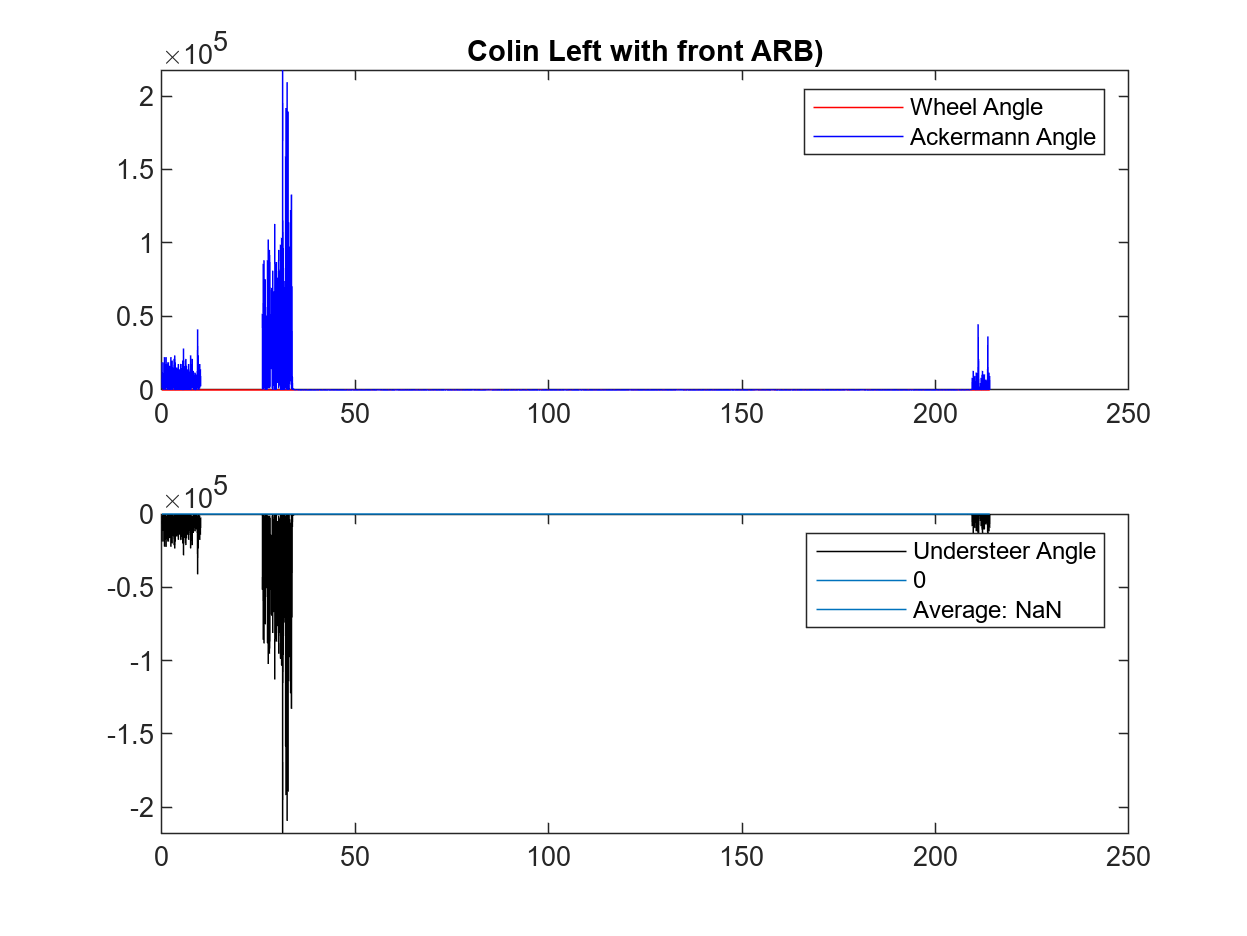

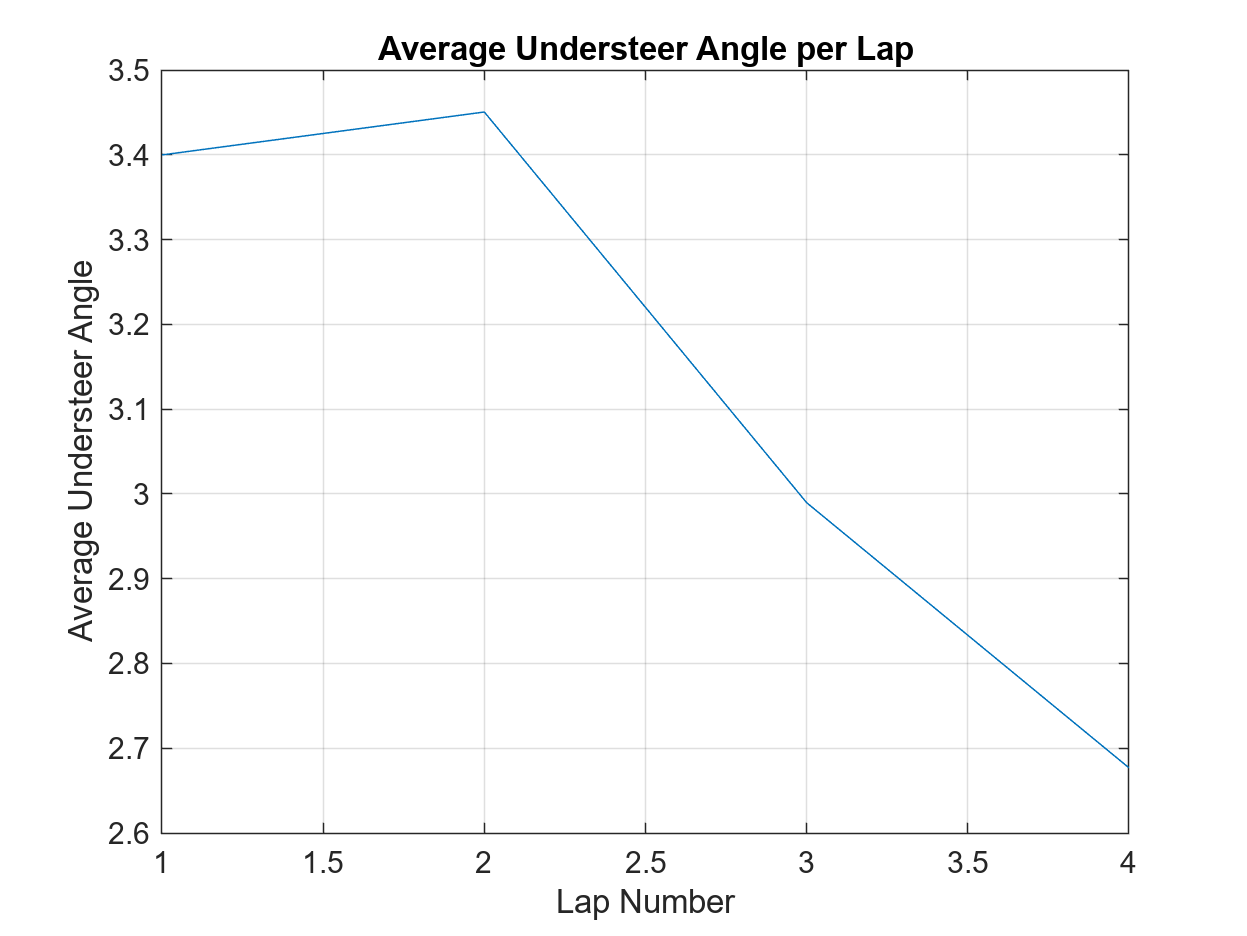

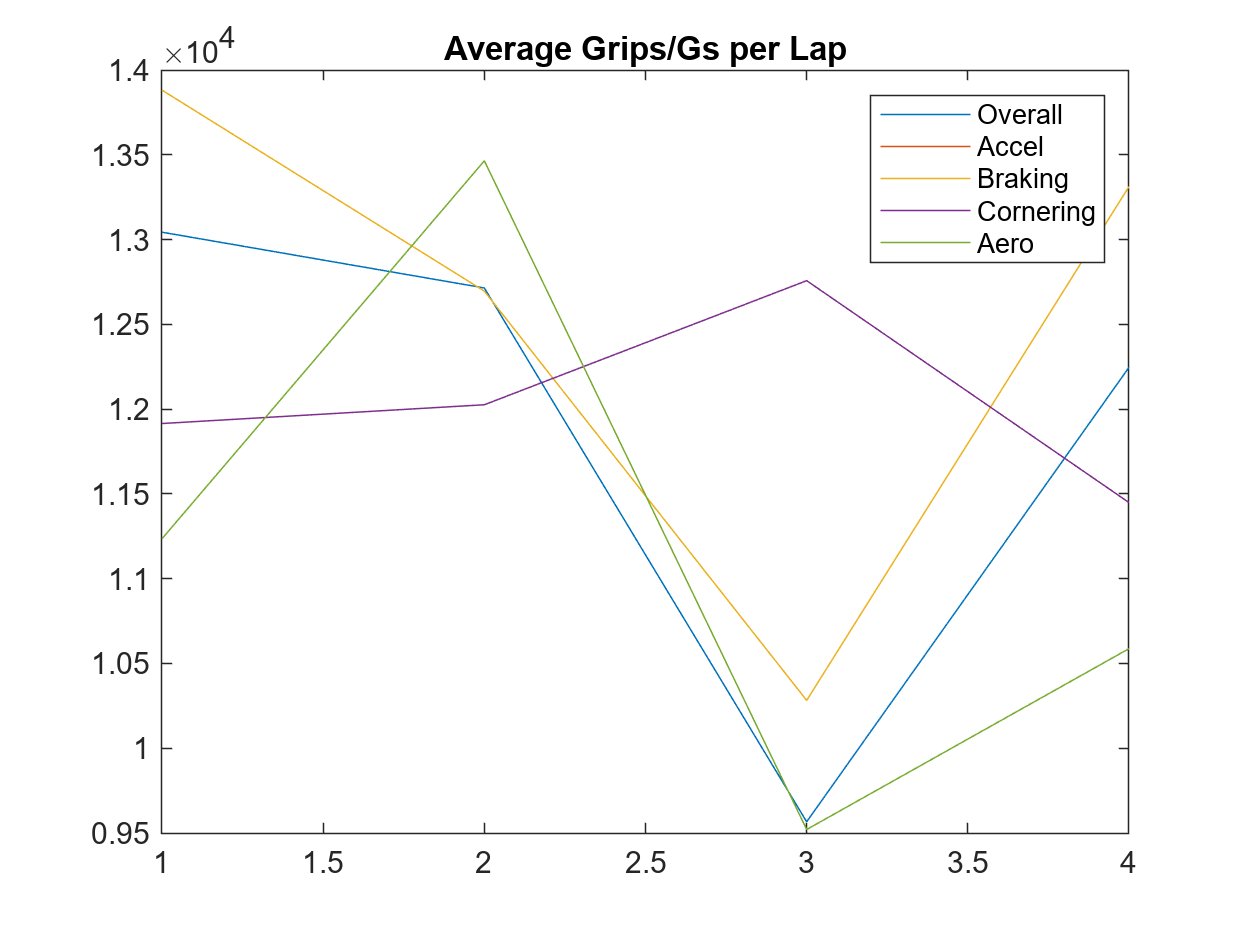

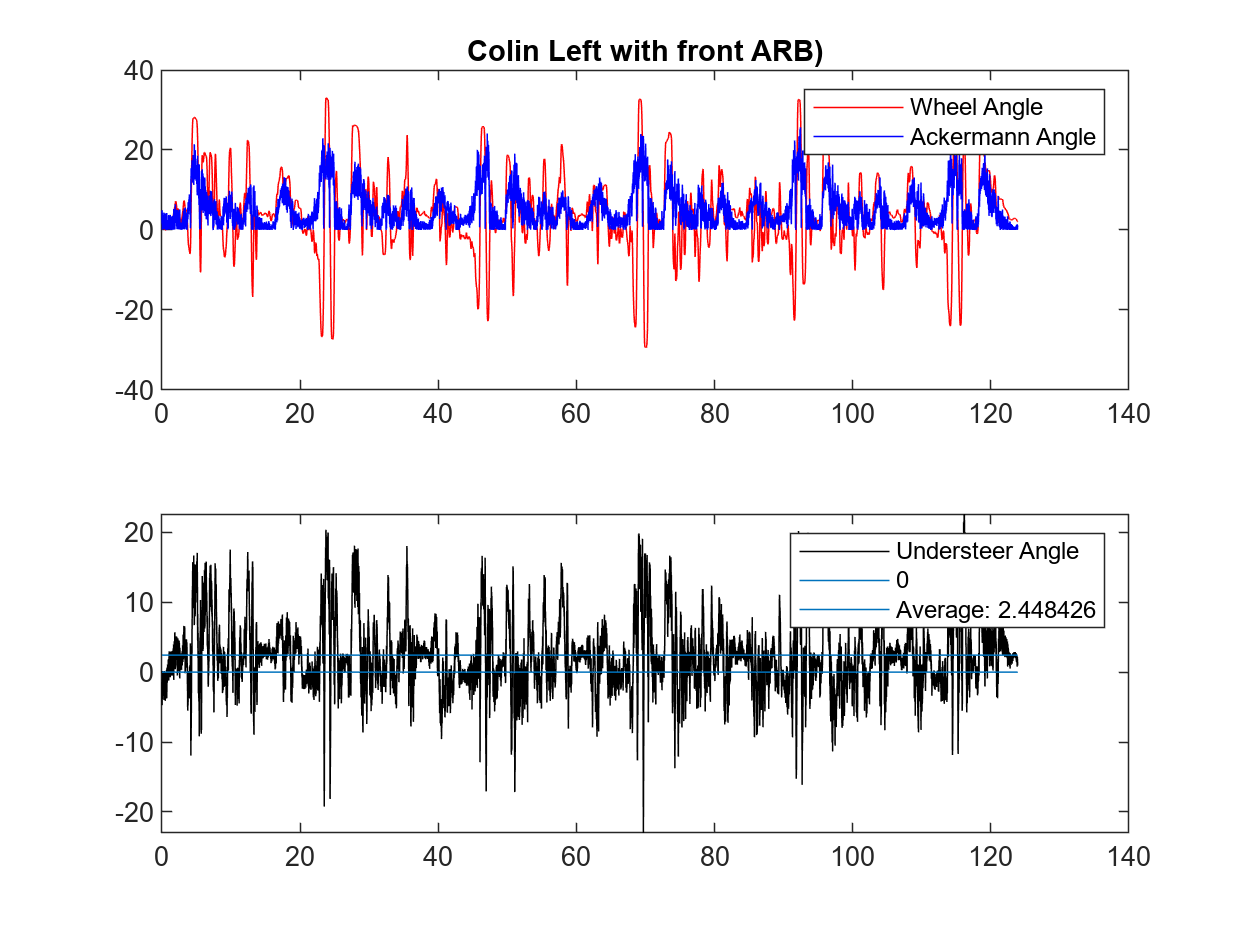

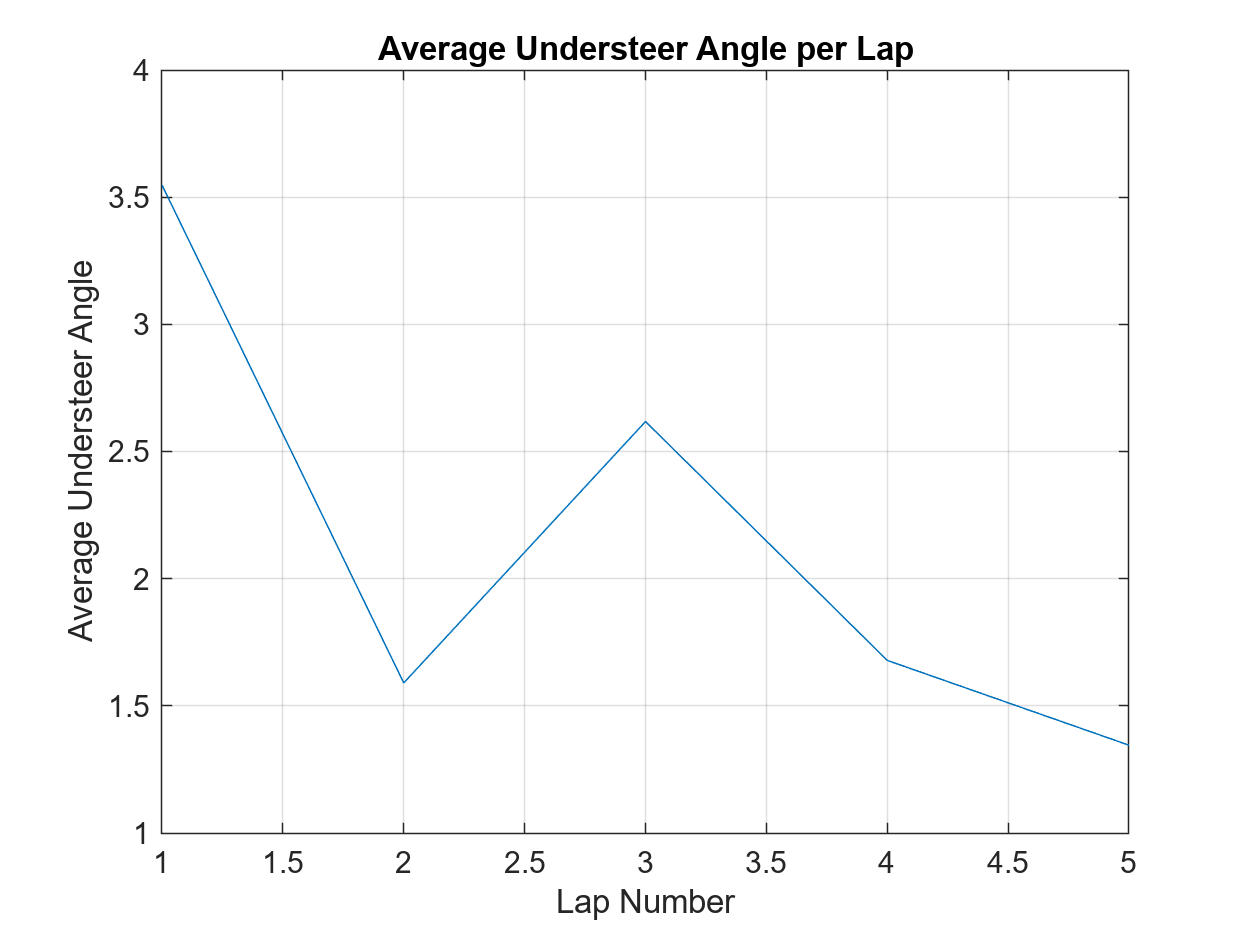

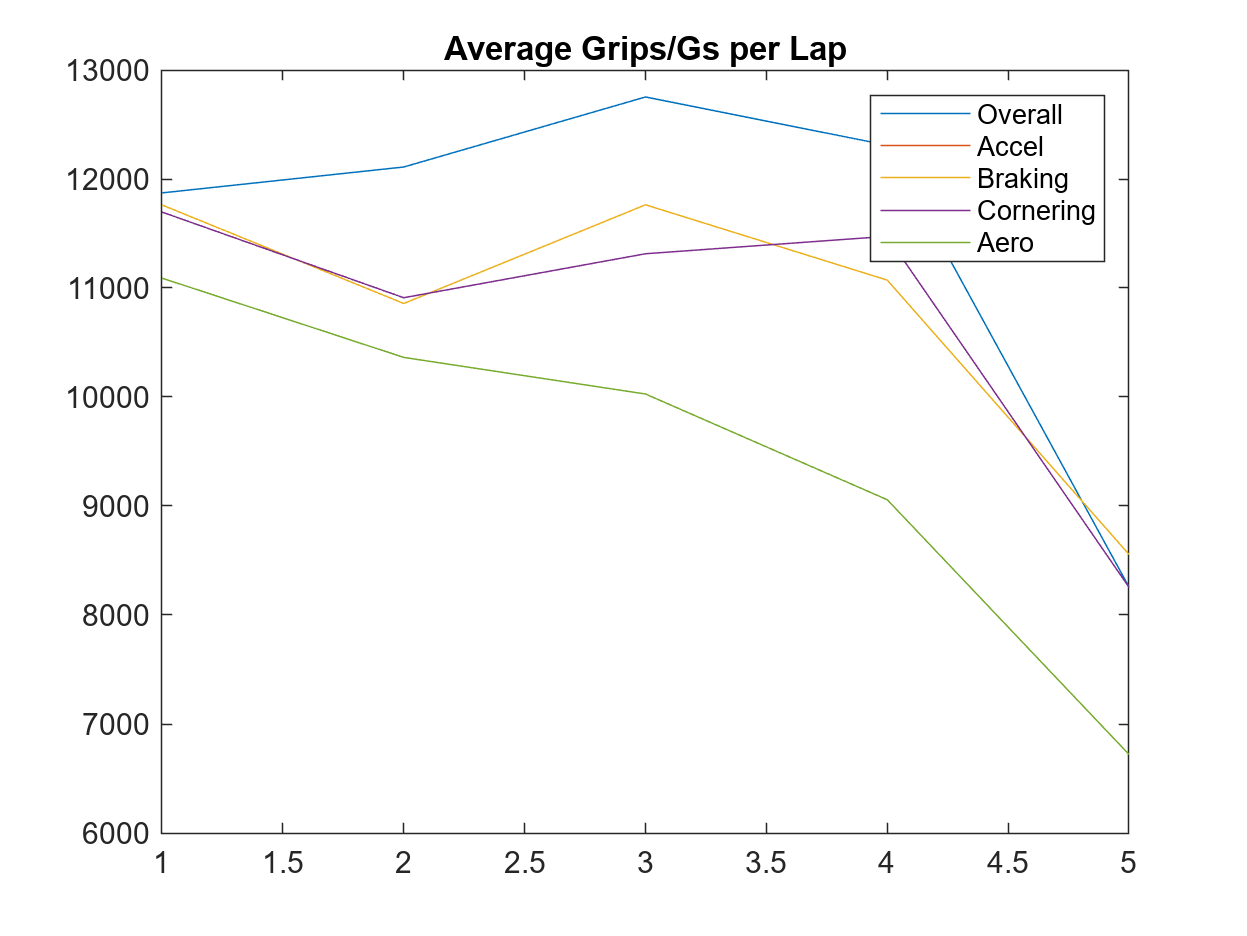

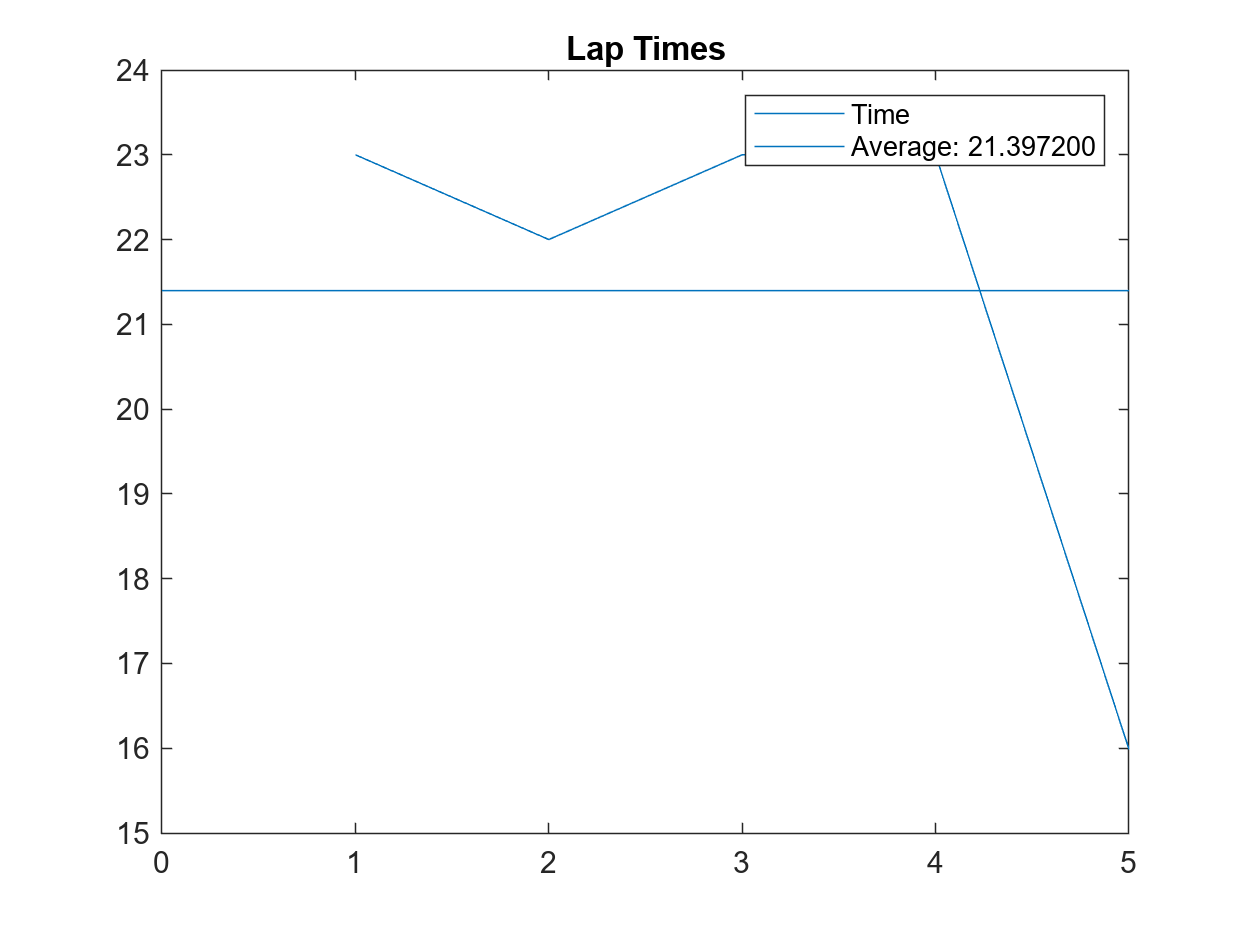

for currentRun = 1:NumberOfRuns
    [filename, path] = uigetfile('*.csv', 'Select MoTeC Output File');
    % filename = "Colin5LapAutocross.csv";
    % path = "./Data";
    run = motecImport(filename, path);

    % HELPER VARIABLES 
    if GTYPE == "IMU"
        gLat = run.VehicleAccelLateralIMU;
        gLong = run.VehicleAccelLongIMU;
    else % C185
        gLat = lapTrimRun.GForceLatC185;
        gLong = lapTrimRun.GForceLongC185;
    end
    
    if SPEEDMODE == "GroundSpeed"
        Speed = run.GroundSpeed;
    elseif SPEEDMODE == "DriveSpeed"
        Speed = run.DriveSpeed;
    else % GPS
        Speed = run.GPSSpeed;
    end
    
    time = run.Time;
    
    car = FB2223();
    
    % Calculations
    [UA, AA, WA] = UndersteerAngle(gLat,Speed,run.SteeredAngle,car);
    
    % Lap Loop
    [lapZero, lapMax] = LapFinder(run);
    for i = 1:lapMax-lapZero
        i1 = find(run.LapNumber == lapZero + i,1);
        if lapZero+i==lapMax
            [i2,~] = size(lapTrimRun.LapNumber);
        else
            i2 = find(run.LapNumber > lapZero + i,1);
        end
        Lap(i) = i;
        lapTimes(i) = time(i2) - time(i1);
        [UA1, AA1, WA1] = UndersteerAngle(gLat(i1:i2), ...
            Speed(i1:i2), run.SteeredAngle(i1:i2),car);
        avgUA(i) = mean(UA1);
        [GO, GB, GA, GC, GAero] = GripSubsets(gLat(i1:i2), gLong(i1:i2),Speed(i1:i2));
        avgGO(i) = mean(GO);
        avgGB(i) = mean(GB);
        avgGA(i) = mean(GA);
        avgGC(i) = mean(GC);
        avgGAero(i) = mean(GAero);
    end
    
    OverallGrips = GripSubsets(gLat, gLong, Speed);
    
    % Plotting
    clf;
    figure
    UndersteerDisplay("Colin Left with front ARB)", time, WA, AA, UA);
    
    figure
    plot(Lap, avgUA); grid on; title('Average Understeer Angle per Lap'); 
    xlabel('Lap Number'); ylabel('Average Understeer Angle')
    
    figure
    plot(Lap, avgGO, ...
        Lap, avgGA, ...
        Lap, avgGB, ...
        Lap, avgGC, ...
        Lap, avgGAero)
    title("Average Grips/Gs per Lap")
    legend('Overall','Accel','Braking','Cornering','Aero')
    
    figure
    plot(Lap,lapTimes)
    title("Lap Times")
    line([0 max(Lap)], [mean(lapTimes) mean(lapTimes)])
    legend('Time', sprintf('Average: %f', mean(lapTimes)))
end